# Substitution Practice

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

A thorough understanding of the integral as an antiderivative can only take you so far. Just as with derivatives, there are integration rules that can be built through the combination of functions as well. The method of substitution that will be discussed in this live script applies to nearly every integral you will ever calculate. In fact, you will likely forget that you are even applying it in some cases because it will become so natural to use!

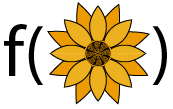

The method of substitution allows you to replace a complicated integral with a simpler one.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

clear gPrime uPrime NewMeasure Measure g fa fb fc fu f MyFun MyAnswer LastFive
 

## **Practice using substitution**

Rewrite each of the following integrals in terms of the new variable provided by the substitution function,$\displaystyle \int f(g(x))g'(x)dx = \int f'(g)\; dg.$. Then solve the integral.

### **Exercise 1**

$\displaystyle \int 15\sin(3x^5)x^4\; dx$ where $g(x) = 3x^5$

First, find the derivative of $g(x)$ with respect to $x$:

gPrime = @(x) 15*x^4;

What is the new measure $dg$ going to be in terms of $x$ and $dx$?

NewMeasure = @(x,dx)15*x^4*dx;

If we define $\displaystyle \int 15\sin(3x^5)x^4\; dx = \int f(g)\; dg$, what is $f(g)$?

fa = @(g) sin(g);

Calculate the function $F(x) = \displaystyle \int 15\sin(3x^5)x^4\; dx$.

Answer = @(x,C)  -cos(3*x^5)+C;
Check1a(gPrime,fa,NewMeasure,Answer);
 

  **Note: **In many textbooks it is common to use a variable $u$ in place of the variable $g$ or even to call this method $u$-substitution. 

### Exercise 2

$\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$ where $u(t) = \frac{1+t}{t^2+5}$ 

Calculate the derivative $u'(t)$.

uPrime = @(t)  1/(t^2+5)-(1+t)*(t^2+5)^(-2)*2*t;

Calculate the new bounds and new measure for the integral in terms of $u$. 

ua = 2/6;
gb = 4/14;
NewMeasure = @(t,dt)(1/(t^2+5)-(2*t*(t+1))/(t^2+5)^2)*dt;

If we define $\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt = \int_{u(a)}^{u(b)} f(u)\cdot du$, what is $f(u)$?

f = @(u)u^(2/3);

Calculate the function $F(t) = \displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$.

try
    Answer =  3/5*((2/7)^(5/3)-(1/3)^(5/3));
catch ME
    if contains(ME.message,"Unrecognized function or variable")
        Answer = 0;
        warning("This is a definite integral. Your solution should be a number.")
    else
        rethrow(ME)
    end
end
Check1b(uPrime,f,ua,gb,NewMeasure,Answer);
 

### **Exercise 3**

$\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ where $q(r) = e^r-17$ 

Remember that $e^x$ is written as `exp(x)` in MATLAB.

gPrime = @(r) exp(r);
NewMeasure = @(r,dr)exp(r)*dr;

If we define $\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ $= \int f(q)\cdot \; dq$,

fc = @(q) cos(q);
Answer = @(r,C) sin(exp(r)-17)+C;
Check1c(gPrime,fc,NewMeasure,Answer);
 

### **Exercise 4**

$\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ where $g(w) = 1+w^2$. 

gPrime = @(w) 2*w;
ga = 2;
gb = 5;
measure = @(w,dw)2*w*dw;

Remember that $\ln(g)$ is written `log(g)` in MATLAB.

If we define $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ $= \displaystyle \int_{g(a)}^{g(b)}f(g)\cdot dg,$

fb = @(g)  log(g)^7*1/2/g;

This result is still not immediately computable, so let's make another substitution with $u(g) = \ln(g)$. 

If we define $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ $= \displaystyle \int_{u(a)}^{u(b)}f(u)\cdot du,$

ua = log(2);
ub = log(5);

Calculating $du$ as a function of $g$:

nextMeasure = @(g,dg)1/g*dg;
fu = @(u) u^7/2;

Putting everything together, compute the result:

Answer = ((log(5))^8-(log(2))^8)/16;
Check1d(gPrime,fb,ga,gb,measure,nextMeasure,ua,ub,fu,Answer);
 

## Practice Randomized Substitution Integrals

  **Pro-tip**. MATLAB syntax is 7`*t^(2/3)` for $7t^{2/3}$. The variable you use in the solution matters, as does appropriate use of parentheses and multiplication operators.

**Solution: **Answers vary

### Practice App

You can practice in the Calculus Flashcards app. You can start the app by clicking on the image below. You should set the problem type to be "Substitution" in the Integrals section. The app will open in a new window.

[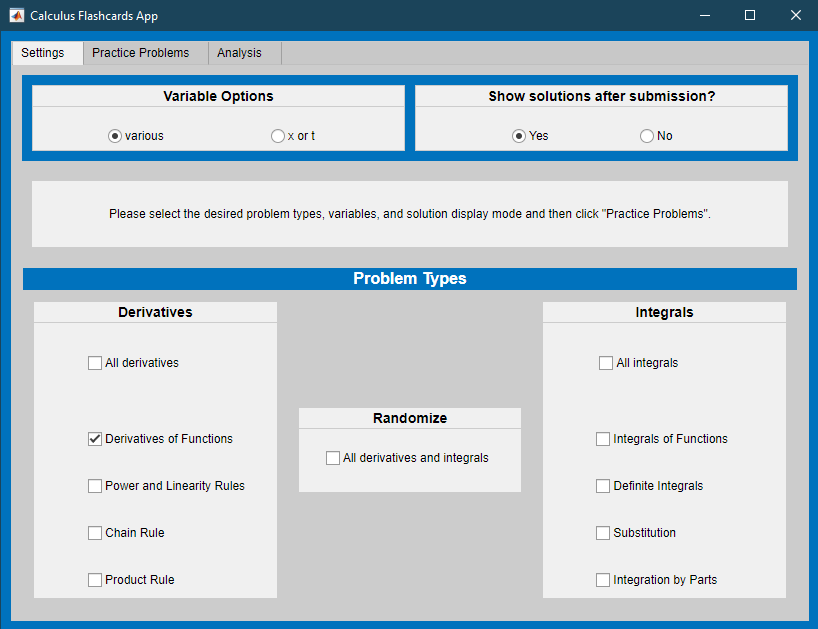](matlab: CalculusFlashcards)

[Calculus Flashcards App](matlab: CalculusFlashcards)

 
run("CalculusFlashcards.mlapp")

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

**Exercise 1 Solutions**

a. $\displaystyle \int 15\sin(3x^5)x^4\; dx$ where $g(x) = 3x^5$

function Check1a(gp,fsub,newMeasure,soln)
syms C x g dx dg %#ok<NASGU>
fg = @(g) sin(g);
gpans = @(x) diff(3*x^5,x);
measAns(x,dx) = gpans*dx;
correctAns = @(x,C)int(15*sin(3*x^5)*x^4,x)+C;
if isequal(gp(x),x) && isequal(fsub(g),g) && isequal(newMeasure(x,dx),dx) && isequal(soln(x,C),x)
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(x)==gpans(x),"Unknown","false");
    a2 = isAlways(fg(x)==fsub(x),"Unknown","false");
    a3 = isAlways(newMeasure(x,dx) == measAns(x,dx),"Unknown","false");
    a4 = isAlways(correctAns(x,C)==soln(x,C),"Unknown","false");
    if a1
        displayFormula(['"Correct.  "' "dg/dx = gpans"])
    else
        disp("You do not have the correct function for g'(x).")
    end
    if a3
        displayFormula(['"Correct. The new measure is "' "dg = measAns"])
    else
        disp("Incorrect measure.")
    end
    if a2
        displayFormula(['"Correct.  "' "f(g) = fg"])
    else
        disp("You do not have the correct function for f(g)")
    end
    if a4
        displayFormula(['"Correct.  "' "int(15*sin(3*x^5)*x^4,x) = correctAns"])
    elseif isAlways(correctAns(x,0)==soln(x,0),"Unknown","false")
        disp("Incorrect. You forgot the +C.")
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~a2 ~a3 ~a4])
        disp("Please try again.")
    end
end
end

b. $\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$ where $u(t) = \frac{1+t}{t^2+5}$

function Check1b(gp,fsub,ua,ub,newMeasure,soln)
syms t u du dt a b %#ok<NASGU>
ut = @(t) (1+t)/(t^2+5);
fg = @(u) u^(2/3);
gpans = @(t) diff((1+t)/(t^2+5),t);
uaVal = ut(1);
ubVal = ut(3);
measAns = @(t,dt) gpans*dt;
correctAns = int(((1+t)/(t^2+5))^(2/3)*(5-2*t-t^2)/(t^2+5)^2,t,[1 3]);
if isequal(gp(t),t) && isequal(fsub(u),u) && ua == 1 && ub == 3 && isequal(newMeasure(t,dt),dt) && soln == 0
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(t)==gpans(t),"Unknown","false");
    a2 = isAlways(fg(t)==fsub(t),"Unknown","false");
    a5 = uaVal == ua;
    a6 = ubVal == ub;
    a3 = isAlways(newMeasure(t,dt) == measAns(t,dt),"Unknown","false");
    a4 = abs(double(correctAns)-soln)<10*eps;
    if a1
        displayFormula(['"Correct.  "' "du/dt = gpans"])
    else
        disp("You do not have the correct function for u'(t).")
    end
    if a3
        displayFormula(['"Correct. The new measure is "' "du = measAns"])
    else
        disp("Incorrect measure.")
    end
    if a2
        displayFormula(['"Correct.  "' "f(u) = fg"])
    else
        disp("You do not have the correct function for f(u)")
    end
    if a5 && a6
        displayFormula(['"You have the correct values for the bounds of the integral: "' "u(a) = ua" '" and "' "u(b)=ub"])
    elseif ~a5 && ~a6
        disp("You have not calcuated the correct values for the bounds of the integral.")
    elseif a5
        disp("You have calcuated the correct lower bound, but not the correct upper bound.")
    else
        disp("You have calculated the correct upper bound, but not the correct lower bound.")
    end
    if a4
        decimalAns = vpa(correctAns); %#ok<NASGU>
        displayFormula(['"Correct, the value of this integral is "' "correctAns = decimalAns"])
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~a2 ~a3 ~a4 ~a5 ~a6])
        disp("Please try again.")
    end
end
end

c $\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ where $q(r) = e^r-17$ 

function Check1c(gp,fsub,newMeasure,soln)
syms C x r q dq dr %#ok<NASGU>
fg = @(q) cos(q);
gpans = @(r) diff(exp(r)-17,r);
measAns = @(r,dr)gpans*dr;
correctAns = @(r,C)int(exp(r)*cos(exp(r)-17),r)+C;
if isequal(gp(r),r) && isequal(fsub(q),q) && isequal(newMeasure(r,dr),dr) && isequal(soln(r,C),r)
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(x)==gpans(x),"Unknown","false");
    a2 = isAlways(fg(x)==fsub(x),"Unknown","false");
    a3 = isAlways(newMeasure(r,dr)==measAns(r,dr),"Unknown","false");
    try
        a4 = isAlways(correctAns(x,C)==soln(x,C),"Unknown","false");
    catch ME
        a4 = false;
        if ME.message == "Unrecognized function or variable 'q'."
            a4flag = "q";
        else
            rethrow(ME)
        end
    end
    if a1
        displayFormula(['"Correct.  "' "dq/dr = gpans"])
    else
        disp("You do not have the correct function for q'(r).")
    end
    if a3
        displayFormula(['"Correct. The new measure is "' "dq = measAns"])
    else
        disp("Incorrect measure.")
    end
    if a2
        displayFormula(['"Correct.  "' "f(q) = fg"])
    else
        disp("You do not have the correct function for f(q)")
    end
    if a4
        displayFormula(['"Correct.  "' "int(exp(r)*cos(exp(r)-17),r) = correctAns"])
    elseif exist("a4flag","var") && a4flag == "q"
        displayFormula(['"The solution should be a function of "' "r" '" not "' "q"])
    elseif isAlways(correctAns(x,0)==soln(x,0),"Unknown","false")
        disp("Incorrect. You forgot the +C.")
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~a2 ~a3 ~a4])
        disp("Please try again.")
    end
end
end

d. $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ where $g(w) = 1+w^2$. 

function Check1d(gp,fgsub,ua,ub,newMeas1,newMeas2,ua2,ub2,fusub,soln)
syms t w g u dg du dw a b %#ok<NASGU>
% First substitution
ut = @(w) 1+w^2;
fg = @(g) (log(g))^7*(0.5/g);
gpans = @(w) diff(1+w^2,w);
gaVal = ut(-1);
gbVal = ut(2);
% Second substitution
uw = @(w) log(1+w^2);
uaVal = uw(-1);
ubVal = uw(2);
fu = @(u) 0.5*u^(7);
measAns = @(w,dw)gpans*dw;
meas2Ans = @(g,dg)diff(log(g),g)*dg;
correctAns = int((log(1+w^2))^7*(w/(1+w^2)),w,[-1 2]);
if isequal(gp(w),w) && isequal(fgsub(g),g) && ua == -1 && ub == 2 && isequal(newMeas1(g,dg),dg) && soln == 0 ...
        && isequal(newMeas2(g,dg),dg) && ua2 == -1 && ub2 == 2 && isequal(fusub(u),u)
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(t)==gpans(t),"Unknown","false");
    a2 = isequal(fg(t),fgsub(t));
    a5 = gaVal == ua;
    a6 = gbVal == ub;
    a3 = isAlways(newMeas1(w,dw) == measAns(w,dw),"Unknown","false");
    a4 = abs(double(correctAns)-soln)<10*eps;
    a7 = isAlways(newMeas2(g,dg) == meas2Ans(g,dg),"Unknown","false");
    a8 = isequal(fu(t),fusub(t));
    a9 = uaVal == ua2;
    a10 = ubVal == ub2;
    if a1
        displayFormula(['"Correct.  "' "dg/dw = gpans"])
    else
        disp("You do not have the correct function for g'(w).")
    end
    if a3
        displayFormula(['"Correct. The new measure for the first integral is "' "dg = measAns"])
    else
        disp("Incorrect measure.")
    end
    if a2
        displayFormula(['"Correct.   "' "f(g) = fg"])
    else
        disp("You do not have the correct function for f(g)")
    end
    if a5 && a6
        displayFormula(['"You have the correct values for the bounds of the first integral: "' "g(a) = ua" '" and "' "g(b)=ub"])
    elseif ~a5 && ~a6
        disp("You have not calcuated the correct values for the bounds of the first integral.")
    elseif a5
        disp("You have calcuated the correct lower bound, but not the correct upper bound of the first integral.")
    else
        disp("You have calculated the correct upper bound, but not the correct lower bound of the first integral.")
    end
    if a9 && a10
        displayFormula(['"You have the correct values for the bounds of the second integral: "' "u(a) = log(ua)" '" and "' "u(b) = log(ub)"])
    elseif ~a9 && ~a10
        disp("You have not calcuated the correct values for the bounds of the second integral.")
    elseif a9
        disp("You have calcuated the correct lower bound, but not the correct upper bound of the second integral.")
    else
        disp("You have calculated the correct upper bound, but not the correct lower bound of the second integral.")
    end
    if a7 && a8
        displayFormula(['"Correct. The new measure for the second integral is "' "du = measAns";...
            '" and the integrand is "' "f(u) = fu"])
    elseif a7 && ~a8
        disp("Correct measure, but incorrect integrand in the second integral.")
    elseif ~a7 && a8
        disp("Incorrect measure, but correct integrand in the second integral.")
    else
        disp("Incorrect measure and incorrect integrand in the second integral.")
    end 
    if a4
        displayFormula(['"Correct, the value of this integral is "' "int((log(1+w^2))^7*(w/(1+w^2)),w,[-1 2])==correctAns"])
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~(a2&a3) ~a4 ~a5 ~a6 ~(a7&a8)])
        disp("Please try again.")
    end
end
end